% Analytical calculation for the diffracted wave S for TP-VHG
% PG 401, Eqn: (11-67)
clear; close all; clc;

% Set up electric field form, chi and Phi have no physical meaning yet
syms chi Phi
S = 1j * exp(1j*chi) * sin(Phi * sqrt(1 + (chi^2 / Phi^2))) / sqrt(1 + (chi^2 / Phi^2))

$$S = \frac{{\mathrm{e}}^{\chi \,\mathrm{i}}\,\sin\left(\Phi \,\sqrt{\frac{\chi^{2}}{\Phi^{2}}+1}\right)\,\mathrm{i}}{\sqrt{\frac{\chi^{2}}{\Phi^{2}}+1}}$$

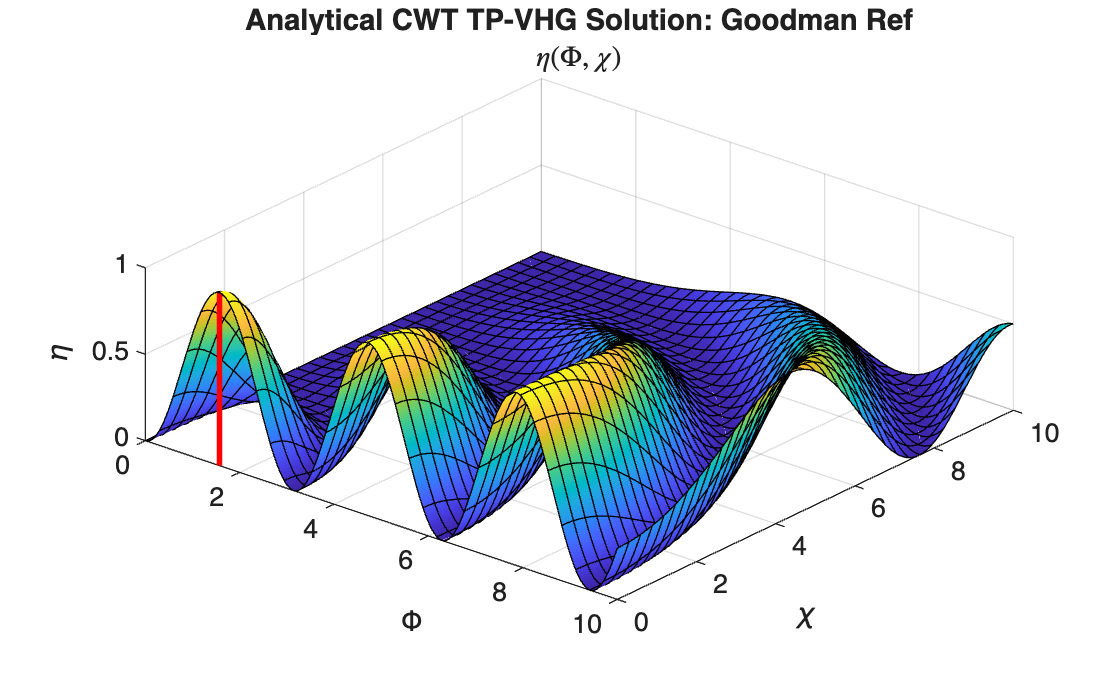


% Intensity of diffracted wave
S_Int = abs(S)^2;

% Plot analytical intensity
fsurf(S_Int);
hold on;  % keep the existing surface plot
title('Analytical CWT TP-VHG Solution: Goodman Ref')
subtitle('$\eta(\Phi,\chi)$','Interpreter','latex');
xlabel('\Phi'); ylabel('\chi'); zlabel('\eta');
xlim([0 10]); ylim([0 10]);

zLimits = get(gca, 'ZLim');  % get current z-axis limits
plot3(pi/2 * [1 1], [0 0], zLimits, 'r-', 'LineWidth', 2);  % plot the vertical red line

view([40 55]) % Psuedo-Goodman view

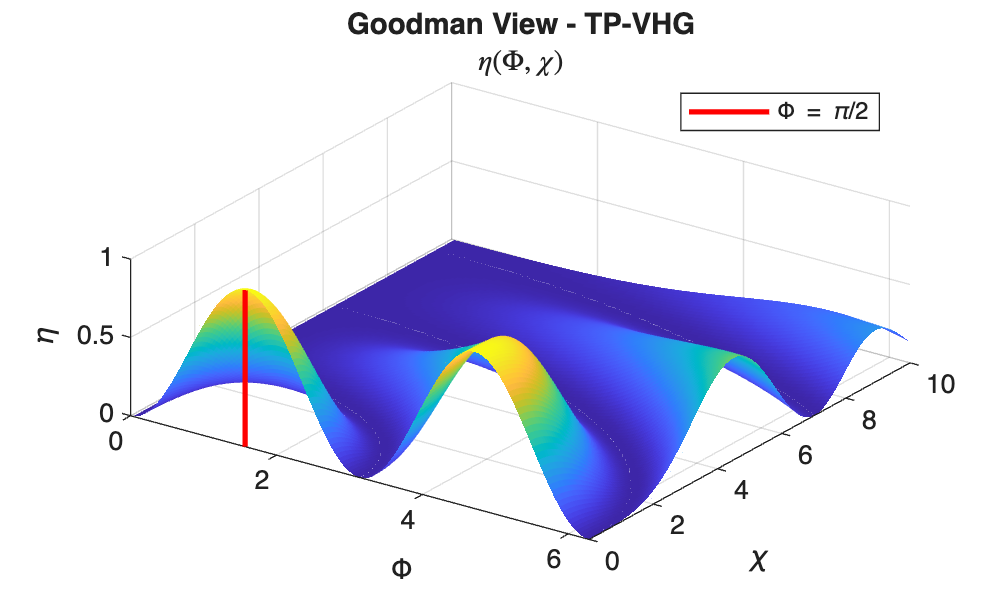

% Now let's fix the function to output both the way we want, then we can
% take slices or do traces through either dimension
clear; close all; clc;

% Set ranges
chi_range = 20;   % chi is detuning (Angle)
Phi_range = 3*pi; % Phi is grating strength (Depth)

% Set variable space
N = 2^8;
chi_min = -chi_range/2;
chi_max =  chi_range/2;

% Make variables
chi = linspace(chi_min,chi_max,N);
Phi = linspace(0,Phi_range,N); clear N;

% Calculate CWT Solution for diffracted wave and intensity
[S, S_int] = S_wave(Phi,chi);

% Isolate the on-Bragg condition for grating strength (depth)
bragg_match_chi  = 0; % chi = 0
[~, chi_idx] = findClosestNumber(chi, bragg_match_chi); % find this index
S_int_BraggMatch = S_int(chi_idx,:); % S_int(chi,Phi) (annoyingly)

% Isolate the maximum DE condition of Phi = pi/2 (angle at max)
max_DE_Phi = pi/2; % Phi = pi/2
[~, Phi_idx] = findClosestNumber(Phi, max_DE_Phi); % find this index
S_int_Max  = S_int(:,Phi_idx)';

% Make mesh for 3D plotting
[PHI,CHI] = meshgrid(Phi,chi);

% Plot 3D View in the Goodman style
figure;
surf(PHI,CHI,S_int); shading flat;
title('Goodman View - TP-VHG')
subtitle('$\eta(\Phi,\chi)$','Interpreter','latex')
xlabel('\Phi'); ylabel('\chi'); zlabel('\eta');
xlim([0,2*pi]); ylim([0,10]); zlim([0 1]);
% Add the vertical red line at x = pi/2 and y = 0
hold on; plot3(pi/2 * [1 1], [0 0], [0 1], 'r-', 'LineWidth', 2); hold off;
legend('','\Phi = \pi/2','Location','best'); view([35 54]); % Goodman view

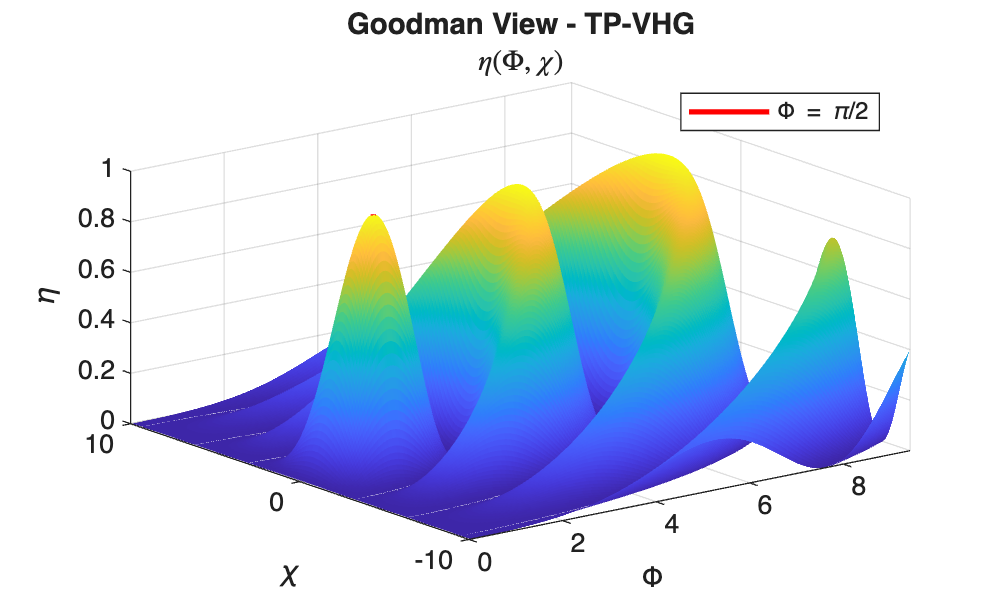


% Plot 3D View in the default
figure;
surf(PHI,CHI,S_int); shading flat;
title('Goodman View - TP-VHG')
subtitle('$\eta(\Phi,\chi)$','Interpreter','latex')
xlabel('\Phi'); ylabel('\chi'); zlabel('\eta');
xlim([0,Phi_range]); ylim([chi_min,chi_max]); zlim([0 1]);
% Add the vertical red line at x = pi/2 and y = 0
hold on; plot3(pi/2 * [1 1], [0 0], [0 1], 'r-', 'LineWidth', 2); hold off;
legend('','\Phi = \pi/2','Location','best');

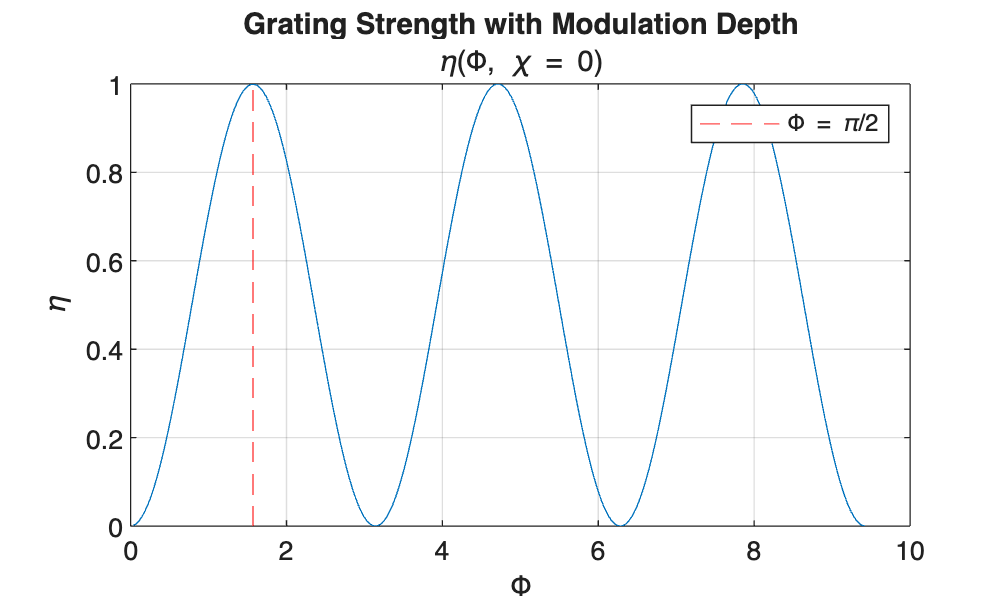


% Plot eta vs Phi (depth dependence)
figure;
plot(Phi,S_int_BraggMatch); grid on;
title('Grating Strength with Modulation Depth')
subtitle('\eta(\Phi, \chi = 0)');
xline(max_DE_Phi,'r--');
yticks(0:0.2:1);
xlabel('\Phi'); ylabel('\eta');
legend('','\Phi = \pi/2')

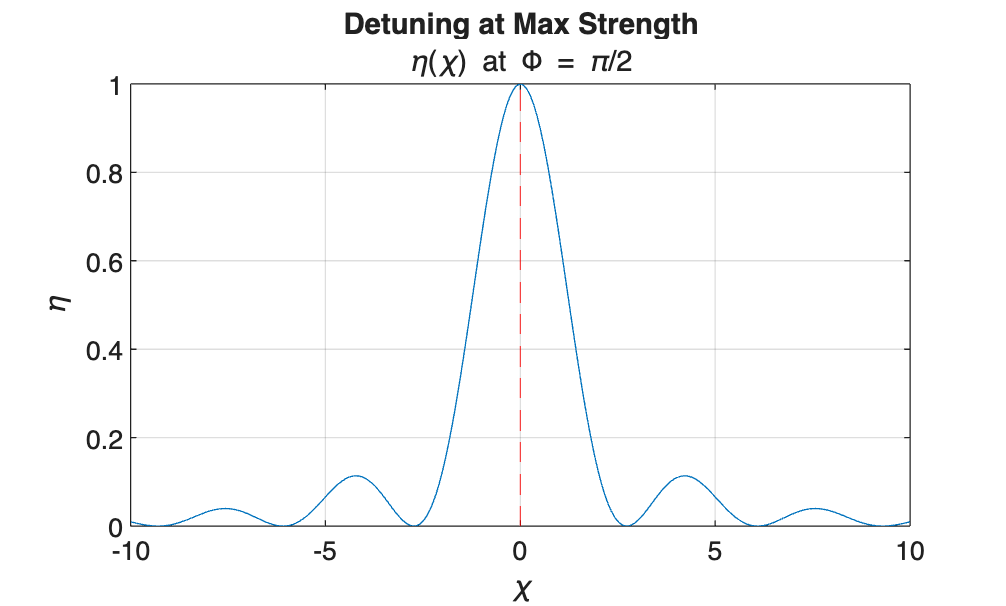


% Plot eta vs chi (angle dependence)
figure;
plot(chi,S_int_Max); grid on;
title('Detuning at Max Strength');
subtitle('\eta(\chi) at \Phi = \pi/2')
xline(bragg_match_chi,'r--');
yticks(0:0.2:1);
xlabel('\chi'); ylabel('\eta');

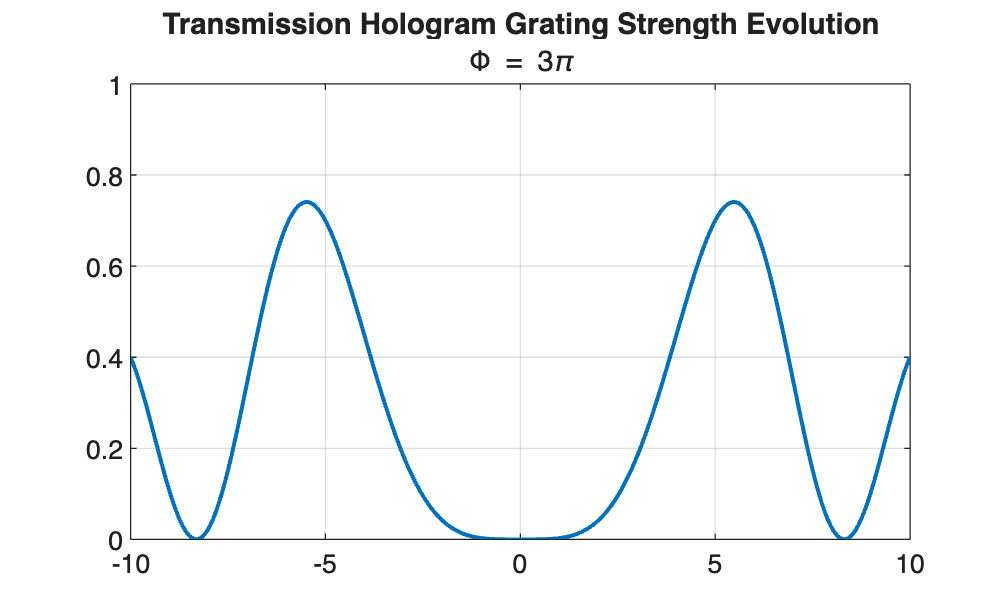

% Video of growth development into overmodulation
figure;
for idx = 1:length(Phi)
    plot(chi,S_int(:,idx),'LineWidth',1.5); % Sweep through grating strength (Phi)
    title('Transmission Hologram Grating Strength Evolution')
    subtitle(['\Phi = ',num2str(round(Phi(idx)/pi,2)),'\pi'])
    ylim([0 1]); yticks(0:0.2:1); xlim([chi_min chi_max]); grid on;
    pause(0.005); drawnow;
end


clear idx;

% Now back to analytics again, let's make the chi and Phi substitutions
clear; close all; clc;

% Define needed syms
syms chi Phi n1 d theta lambda Lambda psi zeta theta_D theta_B lambda_D

% First, the 'starting final' expression
S = 1j * exp(1j*chi) * sin(Phi * sqrt(1 + (chi^2 / Phi^2))) / sqrt(1 + (chi^2 / Phi^2))

$$S = \frac{{\mathrm{e}}^{\chi \,\mathrm{i}}\,\sin\left(\Phi \,\sqrt{\frac{\chi^{2}}{\Phi^{2}}+1}\right)\,\mathrm{i}}{\sqrt{\frac{\chi^{2}}{\Phi^{2}}+1}}$$


% More optical subs
K = 2*pi / Lambda

$$K = \frac{2\,\pi }{\Lambda }$$


% This is the zeta detuning parameter
zeta_sub = K * (theta_D * cos(theta - psi) - (lambda_D / (2*Lambda)))

$$zeta\_sub = -\frac{2\,\pi \,\left(\frac{\lambda_{D}}{2\,\Lambda }-\theta_{D}\,\cos\left(\psi -\theta \right)\right)}{\Lambda }$$


% Phi is the grating strength
Phi_sub = (pi*n1*d) / (lambda * cos(theta))

$$Phi\_sub = \frac{\pi \,d\,n_{1}}{\lambda \,\cos\left(\theta \right)}$$


% chi is the Bragg mismatch parameter
chi_sub = (zeta*d) / (2*cos(theta))

$$chi\_sub = \frac{d\,\zeta }{2\,\cos\left(\theta \right)}$$


% chi_subs is the full version of chi
chi_subs = subs(chi_sub,zeta,zeta_sub)

$$chi\_subs = -\frac{\pi \,d\,\left(\frac{\lambda_{D}}{2\,\Lambda }-\theta_{D}\,\cos\left(\psi -\theta \right)\right)}{\Lambda \,\cos\left(\theta \right)}$$


% S_sub is the fully subbed out version of S in (11-67)
S_sub = subs(S,[Phi, chi],[Phi_sub, chi_subs])

$$S\_sub = \begin{array}{l} \frac{{\mathrm{e}}^{-\frac{\pi \,d\,\left(\frac{\lambda_{D}}{2\,\Lambda }-\theta_{D}\,\cos\left(\psi -\theta \right)\right)\,\mathrm{i}}{\Lambda \,\cos\left(\theta \right)}}\,\sin\left(\frac{\pi \,d\,n_{1}\,\sigma_{1}}{\lambda \,\cos\left(\theta \right)}\right)\,\mathrm{i}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{\lambda^{2}\,{\left(\frac{\lambda_{D}}{2\,\Lambda }-\theta_{D}\,\cos\left(\psi -\theta \right)\right)}^{2}}{\Lambda^{2}\,{n_{1}}^{2}}+1} \end{array}$$

S_Mod = subs(S_sub,[Lambda,d,lambda,lambda_D,n1,psi,theta,theta_D],[1E-6,20E-6,532E-9,0,0.001,0,theta,0])

$$S\_Mod = \sin\left(\frac{73786976294838206464\,\pi }{1962733569442696484375\,\cos\left(\theta \right)}\right)\,\mathrm{i}$$

S_Mod_Int = abs(S_Mod)^2

$$S\_Mod\_Int = {\left|\sin\left(\frac{73786976294838206464\,\pi }{1962733569442696484375\,\cos\left(\theta \right)}\right)\right|}^{2}$$

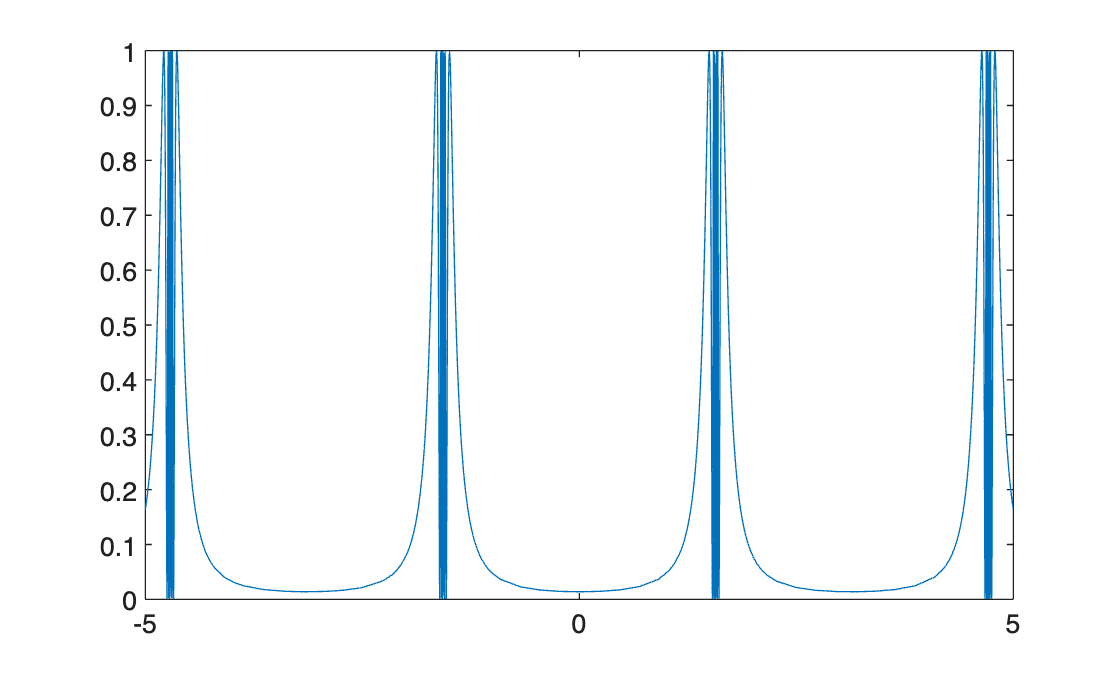

fplot(S_Mod_Int)


% S_sub_int = abs(S_sub)^2

% Now let's just restart again and full send the subs

% Intensity of diffracted wave
S_Int = abs(S)^2;

% Plot analytical intensity
fsurf(S_Int);
hold on;  % keep the existing surface plot
title('$\eta(\Phi,\chi)$','Interpreter','latex');
xlabel('\Phi'); ylabel('\chi'); zlabel('\eta');
xlim([0 10]); ylim([0 10]);

zLimits = get(gca, 'ZLim');  % get current z-axis limits
plot3(pi/2 * [1 1], [0 0], zLimits, 'r-', 'LineWidth', 2);  % plot the vertical red line

view([40 55]) % Psuedo-Goodman view

function [closest, idx] = findClosestNumber(array, target)
% findClosestNumber finds the element in the input array that is closest
% to the specified target value.
% Inputs:
%   array  - A numeric vector (or array) containing the numbers.
%   target - The target numeric value.
%
% Outputs:
%   closest - The element in 'array' that is closest to 'target'.
%   idx     - The index of 'closest' in the input array.

% Validate inputs
if ~isnumeric(array) || ~isscalar(target)
    error('Input "array" must be numeric and "target" must be a numeric scalar.');
end

% Compute the absolute differences between each array element and the target
differences = abs(array - target);

% Find the index of the minimum difference
[~, idx] = min(differences);

% Return the closest value using the index
closest = array(idx);
end

function [S, S_int] = S_wave(Phi,chi)
% function to calculate TP-VHG Diffracted S wave in Goodman (11-67)
% Vectorize inputs
[PHI,CHI] = meshgrid(Phi,chi);
% Calc diffracted wave
S = 1j .* exp(1j.*CHI) .* sin(PHI .* sqrt(1 + (CHI.^2 ./ PHI.^2))) ./ sqrt(1 + (CHI.^2 ./ PHI.^2));
% Calc wave intensity
S_int = abs(S).^2;
end

% function TP_VHG_E1D(Phi_Range,Chi_Range)
% % Numerical calculation of TP-VHG - 1D version
% % PG 401, Eqn: (11-67)
% % Set up electric field form of diffracted wave S
% S = @(Phi,chi) 1j .* exp(1j.*chi) .* sin(Phi .* sqrt(1 + (chi.^2 ./ Phi.^2))) ./ sqrt(1 + (chi.^2 ./ Phi.^2));
%
% % Solution Ranges
% phi1 = Phi_Range(1);
% phi2 = Phi_Range(2);
%
% chi1 = Chi_Range(1);
% chi2 = Chi_Range(2);
%
% x = linspace(phi1,phi2,500);
% y = linspace(chi1,chi2,500);
%
% % Solution space
% [PHI, CHI] = meshgrid(x,y);
%
% % Calculate Diffracted wave
% S_n = S(PHI,CHI);
%
% % Calculate efficiency
% eta_n = abs(S_n).^2; % Intensity of the field
%
% % Plot
% surf(PHI,CHI,eta_n); shading flat;
% title('$\eta(\Phi,\chi)$','Interpreter','latex')
% xlabel('\Phi'); ylabel('\chi'); zlabel('\eta');
% xlim(Phi_Range); ylim(Chi_Range); zlim([0 1]);
%
% % Add the vertical red line at x = pi/2 and y = 0
% hold on;
% zLimits = get(gca, 'ZLim');
% plot3(pi/2 * [1 1], [0 0], zLimits, 'r-', 'LineWidth', 2);
%
% view([35 54]); % Goodman view
% end

% % Numerical calculation of TP-VHG
% % PG 401, Eqn: (11-67)
% clear; close all; clc;
%
% % Assign ranges
% Phi_Range = [0 10];
% Chi_Range = [0 10];
%
% % Plot CWT solution
% figure;
% TP_VHG_E(Phi_Range,Chi_Range);
%
% % Plot a different view of the solution
% Phi_Range = [0 10];
% Chi_Range = [-10 10];
% figure;
% TP_VHG_E(Phi_Range,Chi_Range); view(2)
%
% % Plot a different view of the solution
% Phi_Range = [0 10];
% Chi_Range = [-10 10];
% figure;
% TP_VHG_E(Phi_Range,Chi_Range);

% function TP_VHG_E(Phi_Range,Chi_Range)
% % Numerical calculation of TP-VHG
% % PG 401, Eqn: (11-67)
% % Set up electric field form of diffracted wave S
% S = @(Phi,chi) 1j .* exp(1j.*chi) .* sin(Phi .* sqrt(1 + (chi.^2 ./ Phi.^2))) ./ sqrt(1 + (chi.^2 ./ Phi.^2));
%
% % Solution Ranges
% phi1 = Phi_Range(1);
% phi2 = Phi_Range(2);
%
% chi1 = Chi_Range(1);
% chi2 = Chi_Range(2);
%
% x = linspace(phi1,phi2,500);
% y = linspace(chi1,chi2,500);
%
% % Solution space
% [PHI, CHI] = meshgrid(x,y);
%
% % Calculate Diffracted wave
% S_n = S(PHI,CHI);
%
% % Calculate efficiency
% eta_n = abs(S_n).^2; % Intensity of the field
%
% % Plot
% surf(PHI,CHI,eta_n); shading flat;
% title('$\eta(\Phi,\chi)$','Interpreter','latex')
% xlabel('\Phi'); ylabel('\chi'); zlabel('\eta');
% xlim(Phi_Range); ylim(Chi_Range); zlim([0 1]);
%
% % Add the vertical red line at x = pi/2 and y = 0
% hold on;
% zLimits = get(gca, 'ZLim');
% plot3(pi/2 * [1 1], [0 0], zLimits, 'r-', 'LineWidth', 2);
%
% view([35 54]); % Goodman view
% end

% function TP_VHG(Phi_Range,Chi_Range)
% % DE Function - PG 401:
% eta_n = @(Phi,chi) sin(Phi .* sqrt(1 + (chi.^2 ./ Phi.^2))).^2 ./ (1 + (chi.^2 ./ Phi.^2));
%
% % Solution Ranges
% phi1 = Phi_Range(1);
% phi2 = Phi_Range(2);
%
% chi1 = Chi_Range(1);
% chi2 = Chi_Range(2);
%
% x = linspace(phi1,phi2,500);
% y = linspace(chi1,chi2,500);
%
% % Solution space
% [PHI, CHI] = meshgrid(x,y);
%
% % Calculate DE
% eta_n2 = eta_n(PHI,CHI);
%
% % Plot
% surf(PHI,CHI,eta_n2); shading flat;
% title('$\eta(\Phi,\chi)$','Interpreter','latex')
% xlabel('\Phi'); ylabel('\chi'); zlabel('\eta');
% xline(pi/2,'r--');
% xlim(Phi_Range); ylim(Chi_Range); zlim([0 1]);
%
% view([35 54]); % Goodman view
% end

% clear; close all; clc;
%
% % First, let's start with the end functions for the CWT solution to the
% % Volume Phase Transmission Grating (Goodman (11-67)):
% syms Phi chi
% eta = sin(Phi .* sqrt(1 + (chi^2 / Phi^2))).^2 ./ (1 + (chi^2 / Phi^2))
%
% % Plot analytical
% fsurf(eta)
% xlabel('\Phi'); ylabel('\chi'); zlabel('\eta');
% xlim([0 10]); ylim([0 10]);
%
% view([40 55])

% % Too slow, make numerical version
% clear; close all; clc;
% % DE Function - At Bragg Angle, Chi = 0, PG 402:
% eta_n = @(Phi) sin(Phi).^2;
%
% % Solution Ranges
% Phi = linspace(0,2*pi,1000);
%
% % Calculate DE
% eta_n1 = eta_n(Phi);
%
% % Plot
% plot(Phi,eta_n1)
% title('$\eta(\Phi,\chi = 0)$','Interpreter','latex');
% xlabel('\Phi'); ylabel('\eta');
% xline(pi/2,'r--');
% xlim([0 2*pi]);

% % Now TP-VHG with Bragg Missmatch possible
% clear; close all; clc;
%
% % Assign ranges
% Phi_Range = [0 10];
% Chi_Range = [0 10];
%
% % Plot CWT solution
% TP_VHG(Phi_Range,Chi_Range);